%% ============================================================
%  Compute and export sampled compatibility constant N_sim
%  for the full desired output jet.
%
%  Produces two PDF figures:
%
%  1) 3r_full_jet_all_outputs.pdf
%     All seven compatibility errors e_i^Theta(t), including active outputs.
%     Active outputs should be approximately zero in each interval.
%
%  2) 3r_full_jet_max_inactive.pdf
%     The maximum inactive compatibility error
%         e_max^Theta(t) = max_{i notin sigma(t)} e_i^Theta(t)
%     and the sampled bound N_sim.
%
%  Required Simulink outputs:
%      out.tout
%      out.q
%      out.qd
%      out.dqd
%      out.b1d
%      out.db1d
%      out.b2d
%      out.db2d
%      config.l1
%% ============================================================

clearvars -except out config
close all; clc;

%% ================== CONFIGURATION ==================
outputFileAll = 'plot/3r_full_jet_all_outputs.pdf';
outputFileMax = 'plot/3r_full_jet_max_inactive.pdf';

% One-column paper size, in inches.
figWidth  = 3.45;
figHeight = 3.25;

fontSizeAxes   = 8.5;
fontSizeLabels = 12.0;
fontSizeLegend = 7.0;

lineWidthError  = 1.00;
lineWidthNsim   = 0.95;
lineWidthSwitch = 0.70;

bgOpacity = 0.13;

set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');

colorSwitch = [0.25 0.25 0.25];
colorNsim   = [178 34 34] / 255;
colorMax    = [0 0 0];

deckColors = [
    0.000 0.000 0.000;   % q1
    0.121 0.305 0.474;   % q2
    0.839 0.153 0.157;   % q3
    0.173 0.627 0.173;   % xG1
    0.580 0.404 0.741;   % yG1
    1.000 0.498 0.054;   % xG2
    0.090 0.745 0.811;   % yG2
];

deckLineStyles = {
    '-', ...
    '-', ...
    '-', ...
    '-', ...
    '-', ...
    '-', ...
    '-'
};

meldColors = [
    253, 224, 221;
    252, 197, 192;
    252, 174, 145;
    251, 106,  74;
    222,  45,  38;
    165,  15,  21
] / 255;

meldLabels = {
    '$\sigma_1$', ...
    '$\sigma_2$', ...
    '$\sigma_3$', ...
    '$\sigma_4$', ...
    '$\sigma_5$', ...
    '$\sigma_6$'
};

deckLabels = {
    '$q_1$', ...
    '$q_2$', ...
    '$q_3$', ...
    '$x_{G_1}$', ...
    '$y_{G_1}$', ...
    '$x_{G_2}$', ...
    '$y_{G_2}$'
};

errorLabels = {
    '$e_{q_1}^{\Theta}$', ...
    '$e_{q_2}^{\Theta}$', ...
    '$e_{q_3}^{\Theta}$', ...
    '$e_{x_{G_1}}^{\Theta}$', ...
    '$e_{y_{G_1}}^{\Theta}$', ...
    '$e_{x_{G_2}}^{\Theta}$', ...
    '$e_{y_{G_2}}^{\Theta}$'
};

%% ================== DATA ==================
tvec = out.tout(:).';

q    = squeeze(out.q);
qd   = squeeze(out.qd);
dqd  = squeeze(out.dqd);

b1d  = squeeze(out.b1d);
db1d = squeeze(out.db1d);

b2d  = squeeze(out.b2d);
db2d = squeeze(out.db2d);

q    = ensureRows(q,    3);
qd   = ensureRows(qd,   3);
dqd  = ensureRows(dqd,  3);

b1d  = ensureRows(b1d,  2);
db1d = ensureRows(db1d, 2);

b2d  = ensureRows(b2d,  2);
db2d = ensureRows(db2d, 2);

N = length(tvec);
L = config.l1 * ones(1,3);

fprintf('\nSignal checks:\n');


Signal checks:


fprintf('  max |dqd|  = %.6e\n', max(abs(dqd(:))));

  max |dqd|  = 0.000000e+00


fprintf('  max |db1d| = %.6e\n', max(abs(db1d(:))));

  max |db1d| = 7.853982e-01


fprintf('  max |db2d| = %.6e\n', max(abs(db2d(:))));

  max |db2d| = 5.235988e-01



%% ================== MELD SCHEDULE ==================
activeIntervals = [
    0, 4;
    4, 7;
    7, 9;
    9, 13;
    13, 18;
    18, 22;
];

switchTimes = unique(activeIntervals(:));

% Deck indices:
%
% 1 = q1
% 2 = q2
% 3 = q3
% 4 = x_G1
% 5 = y_G1
% 6 = x_G2
% 7 = y_G2
%
% IMPORTANT:
% This fixed sigmaList must match the sigma actually used in Simulink.
% If Simulink chooses the closest gripper online, the best solution is to
% export out.sigma and reconstruct sigma from it.

sigmaList = {
    [3 4 5];      % sigma_1 = {q3, x_G1, y_G1}
    [2 6 7];      % sigma_2 = {q2, x_G2, y_G2}
    [3 4 5];      % sigma_3 = {q3, x_G1, y_G1}
    [3 6 7];      % sigma_4 = {q3, x_G2, y_G2}
    [1 6 7];      % sigma_5 = {q1, x_G2, y_G2}
    [1 2 3];      % sigma_6 = {q1, q2, q3}
};

%% ================== DESIRED FULL JET ==================
Yd = [
    qd;
    b1d;
    b2d
];

Yd_dot = [
    dqd;
    db1d;
    db2d
];

%% ================== COMPUTE N_sim ==================
Nsim = 0;
maxInfo = struct();

compatibilityError = nan(7, N);
compatibilityErrorInactive = nan(7, N);
compatibilityErrorPosition = nan(7, N);
compatibilityErrorVelocity = nan(7, N);

activeResidual = nan(3, N);
sigmaIndexHistory = nan(1, N);

qGuess = q(:,1);

opts = optimoptions('fsolve', ...
    'Display', 'off', ...
    'FunctionTolerance', 1e-11, ...
    'StepTolerance', 1e-11, ...
    'OptimalityTolerance', 1e-11, ...
    'MaxIterations', 300);

dt = median(diff(tvec));

for k = 1:N
    t = tvec(k);

    % Skip samples close to switching instants, where the desired jet may
    % be discontinuous or not representative of a smooth interval.
    if any(abs(t - switchTimes) < 2*dt)
        continue;
    end

    sigmaIdx = findActiveInterval(t, activeIntervals);
    sigmaIndexHistory(k) = sigmaIdx;

    sigma = sigmaList{sigmaIdx};

    %% ----- reconstruct q_chi from active desired outputs -----
    ySigmaDesired = Yd(sigma, k);

    residualFun = @(qq) deckOutput(qq, L, sigma) - ySigmaDesired;

    try
        qChi = fsolve(residualFun, qGuess, opts);
    catch
        warning('fsolve failed at sample %d, t = %.4f. Retrying from simulated q.', k, t);
        qChi = fsolve(residualFun, q(:,k), opts);
    end

    qGuess = qChi;

    %% ----- evaluate induced full deck position -----
    Ytheta_pos = fullDeckOutput(qChi, L);

    %% ----- reconstruct qdot_chi from active desired velocities -----
    J_deck = fullDeckJacobian(qChi, L);
    J_sigma = J_deck(sigma, :);

    sigmaMin = min(svd(J_sigma));

    yd_sigma_dot = Yd_dot(sigma, k);

    qChi_dot = J_sigma \ yd_sigma_dot;

    %% ----- evaluate induced full deck velocity -----
    Ytheta_dot = J_deck * qChi_dot;

    %% ----- full jet compatibility error -----
    e_pos = Yd(:,k) - Ytheta_pos;

    % Wrap angular errors for q1,q2,q3.
    e_pos(1:3) = atan2(sin(e_pos(1:3)), cos(e_pos(1:3)));

    e_dot = Yd_dot(:,k) - Ytheta_dot;

    e_jet = zeros(7,1);
    for ii = 1:7
        e_jet(ii) = norm([e_pos(ii); e_dot(ii)]);
    end

    compatibilityError(:,k) = e_jet;
    compatibilityErrorPosition(:,k) = abs(e_pos);
    compatibilityErrorVelocity(:,k) = abs(e_dot);

    activeResidual(:,k) = e_jet(sigma);

    inactive = setdiff(1:7, sigma);
    compatibilityErrorInactive(inactive,k) = e_jet(inactive);

    [localMax, localIdx] = max(e_jet(inactive));

    if localMax > Nsim
        Nsim = localMax;

        maxInfo.time = t;
        maxInfo.sample = k;
        maxInfo.sigmaIdx = sigmaIdx;
        maxInfo.sigma = sigma;
        maxInfo.outputIdx = inactive(localIdx);
        maxInfo.error = e_jet(inactive(localIdx));
        maxInfo.e_pos_val = e_pos(inactive(localIdx));
        maxInfo.e_dot_val = e_dot(inactive(localIdx));
        maxInfo.qChi = qChi;
        maxInfo.qChi_dot = qChi_dot;
        maxInfo.sigmaMin = sigmaMin;
        maxInfo.Yd = Yd(:,k);
        maxInfo.Yd_dot = Yd_dot(:,k);
        maxInfo.Ytheta_pos = Ytheta_pos;
        maxInfo.Ytheta_dot = Ytheta_dot;
    end
end

maxActiveResidual = max(activeResidual(:), [], 'omitnan');
eMaxTime = max(compatibilityErrorInactive, [], 1, 'omitnan');

%% ================== REPORT ==================
fprintf('\n============================================\n');

fprintf('Sampled compatibility constant: full jet\n');

Sampled compatibility constant: full jet


fprintf('N_sim = %.6e\n', Nsim);

N_sim = 4.496454e+00


fprintf('============================================\n');


fprintf('Maximum attained at:\n');

Maximum attained at:


fprintf('  time       = %.6f s\n', maxInfo.time);

  time       = 13.020000 s


fprintf('  sample     = %d\n', maxInfo.sample);

  sample     = 1303


fprintf('  sigma idx  = %d\n', maxInfo.sigmaIdx);

  sigma idx  = 5


fprintf('  sigma      = [%s]\n', num2str(maxInfo.sigma));

  sigma      = [1  6  7]


fprintf('  output idx = %d\n', maxInfo.outputIdx);

  output idx = 4


fprintf('  output     = %s\n', deckLabels{maxInfo.outputIdx});

  output     = $x_{G_1}$


fprintf('  max error  = %.6e\n', maxInfo.error);

  max error  = 4.496454e+00


fprintf('  e_pos part = %.6e\n', maxInfo.e_pos_val);

  e_pos part = -4.496454e+00


fprintf('  e_dot part = %.6e\n', maxInfo.e_dot_val);

  e_dot part = 0.000000e+00


fprintf('  sigma_min(J_sigma) = %.6e\n', maxInfo.sigmaMin);

  sigma_min(J_sigma) = 4.024346e-01


fprintf('  qChi = [% .4f  % .4f  % .4f]\n', ...
    maxInfo.qChi(1), maxInfo.qChi(2), maxInfo.qChi(3));

  qChi = [ 0.0000   0.0688   1.8749]


fprintf('  qChi_dot = [% .4e  % .4e  % .4e]\n', ...
    maxInfo.qChi_dot(1), maxInfo.qChi_dot(2), maxInfo.qChi_dot(3));

  qChi_dot = [ 0.0000e+00  -0.0000e+00   0.0000e+00]



fprintf('\nMaximum active-output residual:\n');


Maximum active-output residual:


fprintf('  max ||e_active|| = %.6e\n', maxActiveResidual);

  max ||e_active|| = 3.175238e-12


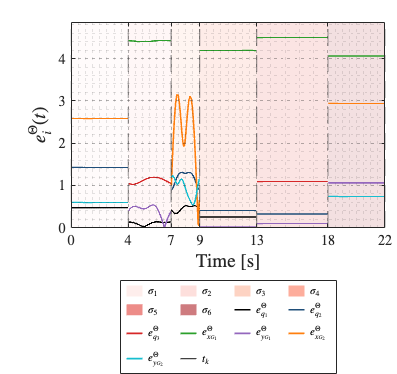


%% ============================================================
%  FIGURE 1: ALL OUTPUTS, WITH MELDS IN LEGEND
%% ============================================================
fig = figure( ...
    'Color', 'w', ...
    'Units', 'inches', ...
    'Position', [1 1 figWidth figHeight], ...
    'PaperUnits', 'inches', ...
    'PaperPosition', [0 0 figWidth figHeight], ...
    'PaperSize', [figWidth figHeight]);

ax = axes(fig);
hold(ax, 'on');

useLogScale = false;

yForLimits = compatibilityError(:);
yForLimits = yForLimits(isfinite(yForLimits));

if isempty(yForLimits)
    yLimits = [0, 1];
else
    yMax = max(yForLimits);
    yLimits = [0, 1.08*yMax];
end

drawMeldBackground(ax, activeIntervals, yLimits, meldColors, bgOpacity);

for i = 1:7
    plot(ax, tvec, compatibilityError(i,:), ...
        'Color', deckColors(i,:), ...
        'LineStyle', deckLineStyles{i}, ...
        'LineWidth', lineWidthError, ...
        'HandleVisibility', 'off');
end

drawSwitchLines(ax, switchTimes, colorSwitch, lineWidthSwitch);

formatAxes(ax, tvec, switchTimes, yLimits, fontSizeAxes, fontSizeLabels, ...
    '$e_i^{\Theta}(t)$');

% Dummy patches for melds in legend.
hMeldDummy = gobjects(6,1);
for s = 1:6
    hMeldDummy(s) = patch(ax, NaN, NaN, meldColors(s,:), ...
        'FaceAlpha', 0.55, ...
        'EdgeColor', 'none', ...
        'DisplayName', meldLabels{s});
end

% Dummy curves for output errors in legend.
hErrDummy = gobjects(7,1);
for i = 1:7
    hErrDummy(i) = plot(ax, NaN, NaN, ...
        'LineStyle', deckLineStyles{i}, ...
        'Color', deckColors(i,:), ...
        'LineWidth', lineWidthError, ...
        'DisplayName', errorLabels{i});
end

hSwitchDummyAll = plot(ax, NaN, NaN, ...
    '--', ...
    'Color', colorSwitch, ...
    'LineWidth', lineWidthSwitch, ...
    'DisplayName', '$t_k$');

legendHandlesAll = [
    hMeldDummy(:);
    hErrDummy(:);
    hSwitchDummyAll
];

legendLabelsAll = [
    meldLabels, ...
    errorLabels, ...
    {'$t_k$'}
];

lg = legend(ax, legendHandlesAll, legendLabelsAll, ...
    'Interpreter', 'latex', ...
    'Location', 'southoutside', ...
    'Orientation', 'horizontal', ...
    'NumColumns', 4, ...
    'FontSize', fontSizeLegend, ...
    'Box', 'on');

lg.ItemTokenSize = [10, 5];
lg.LineWidth = 0.5;

set(ax, 'Position', [0.18 0.39 0.79 0.55]);

set(fig, 'Renderer', 'painters');
exportgraphics(fig, outputFileAll, ...
    'ContentType', 'vector', ...
    'BackgroundColor', 'white');


disp(['Saved PDF figure: ', outputFileAll]);

Saved PDF figure: 3r_full_jet_all_outputs.pdf


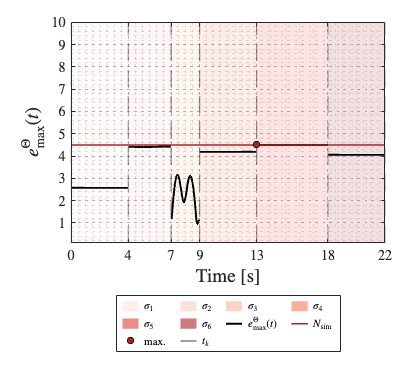


%% ============================================================
%  FIGURE 2: MAXIMUM INACTIVE ERROR
%% ============================================================
fig = figure( ...
    'Color', 'w', ...
    'Units', 'inches', ...
    'Position', [1 1 figWidth figHeight], ...
    'PaperUnits', 'inches', ...
    'PaperPosition', [0 0 figWidth figHeight], ...
    'PaperSize', [figWidth figHeight]);

ax = axes(fig);
hold(ax, 'on');

useLogScale = true;

yForLimits = eMaxTime(:);
yForLimits = yForLimits(isfinite(yForLimits));

if isempty(yForLimits)
    yMin = 1e-12;
    yMax = 1;
else
    yMin = max(min(yForLimits), 1e-12);
    yMax = max(yForLimits);
end

yLimits = [10^floor(log10(yMin)), 10^ceil(log10(max(yMax, yMin*10)))];

drawMeldBackground(ax, activeIntervals, yLimits, meldColors, bgOpacity);

semilogy(ax, tvec, eMaxTime, ...
    'Color', colorMax, ...
    'LineStyle', '-', ...
    'LineWidth', 1.25, ...
    'HandleVisibility', 'off');

semilogy(ax, [tvec(1), tvec(end)], [Nsim, Nsim], ...
    '-', ...
    'Color', colorNsim, ...
    'LineWidth', lineWidthNsim, ...
    'HandleVisibility', 'off');

drawSwitchLines(ax, switchTimes, colorSwitch, lineWidthSwitch);

plot(ax, maxInfo.time, abs(maxInfo.error), ...
    'o', ...
    'MarkerSize', 4.0, ...
    'MarkerFaceColor', colorNsim, ...
    'MarkerEdgeColor', 'k', ...
    'LineWidth', 0.5, ...
    'HandleVisibility', 'off');

formatAxes(ax, tvec, switchTimes, yLimits, fontSizeAxes, fontSizeLabels, ...
    '$e_{\max}^{\Theta}(t)$');

% Dummy patches for melds in legend.
hMeldDummyMax = gobjects(6,1);
for s = 1:6
    hMeldDummyMax(s) = patch(ax, NaN, NaN, meldColors(s,:), ...
        'FaceAlpha', 0.55, ...
        'EdgeColor', 'none', ...
        'DisplayName', meldLabels{s});
end

hMaxErrDummy = plot(ax, NaN, NaN, ...
    '-', ...
    'Color', colorMax, ...
    'LineWidth', 1.25, ...
    'DisplayName', '$e_{\max}^{\Theta}(t)$');

hNsimDummy = plot(ax, NaN, NaN, ...
    '-', ...
    'Color', colorNsim, ...
    'LineWidth', lineWidthNsim, ...
    'DisplayName', '$N_{\mathrm{sim}}$');

hMaxDummy = plot(ax, NaN, NaN, ...
    'o', ...
    'MarkerSize', 4.0, ...
    'MarkerFaceColor', colorNsim, ...
    'MarkerEdgeColor', 'k', ...
    'LineWidth', 0.5, ...
    'DisplayName', 'max.');

hSwitchDummy = plot(ax, NaN, NaN, ...
    '--', ...
    'Color', colorSwitch, ...
    'LineWidth', lineWidthSwitch, ...
    'DisplayName', '$t_k$');

legendHandlesMax = [
    hMeldDummyMax(:);
    hMaxErrDummy;
    hNsimDummy;
    hMaxDummy;
    hSwitchDummy
];

legendLabelsMax = [
    meldLabels, ...
    {'$e_{\max}^{\Theta}(t)$', '$N_{\mathrm{sim}}$', 'max.', '$t_k$'}
];

lg = legend(ax, legendHandlesMax, legendLabelsMax, ...
    'Interpreter', 'latex', ...
    'Location', 'southoutside', ...
    'Orientation', 'horizontal', ...
    'NumColumns', 4, ...
    'FontSize', fontSizeLegend, ...
    'Box', 'on');

lg.ItemTokenSize = [10, 5];
lg.LineWidth = 0.5;

set(ax, 'Position', [0.18 0.35 0.79 0.59]);

set(fig, 'Renderer', 'painters');
exportgraphics(fig, outputFileMax, ...
    'ContentType', 'vector', ...
    'BackgroundColor', 'white');


disp(['Saved PDF figure: ', outputFileMax]);

Saved PDF figure: 3r_full_jet_max_inactive.pdf



%% ============================================================
%  FUNCTIONS
%% ============================================================

function x = ensureRows(x, nRows)
    x = squeeze(x);

    if size(x,1) ~= nRows && size(x,2) == nRows
        x = x.';
    end

    if size(x,1) ~= nRows
        error('Expected signal with %d rows, got size [%d %d].', ...
            nRows, size(x,1), size(x,2));
    end
end

function sigmaIdx = findActiveInterval(t, activeIntervals)
    sigmaIdx = find(t >= activeIntervals(:,1) & t <= activeIntervals(:,2), 1, 'first');

    if isempty(sigmaIdx)
        error('No active interval found for t = %.6f.', t);
    end
end

function y = deckOutput(q, L, indices)
    fullY = fullDeckOutput(q, L);
    y = fullY(indices);
end

function Y = fullDeckOutput(q, L)
    q = q(:);

    q1 = q(1);
    q2 = q(2);
    q3 = q(3);

    l1 = L(1);
    l2 = L(2);
    l3 = L(3);

    c1   = cos(q1);
    s1   = sin(q1);
    c12  = cos(q1 + q2);
    s12  = sin(q1 + q2);
    c123 = cos(q1 + q2 + q3);
    s123 = sin(q1 + q2 + q3);

    xG1 = l1*c1 + 0.5*l2*c12;
    yG1 = l1*s1 + 0.5*l2*s12;

    xG2 = xG1 + 0.5*l2*c12 + l3*c123;
    yG2 = yG1 + 0.5*l2*s12 + l3*s123;

    Y = [
        q1;
        q2;
        q3;
        xG1;
        yG1;
        xG2;
        yG2
    ];
end

function J = fullDeckJacobian(q, L)
    q = q(:);

    q1 = q(1);
    q2 = q(2);
    q3 = q(3);

    l1 = L(1);
    l2 = L(2);
    l3 = L(3);

    s1   = sin(q1);
    c1   = cos(q1);
    s12  = sin(q1 + q2);
    c12  = cos(q1 + q2);
    s123 = sin(q1 + q2 + q3);
    c123 = cos(q1 + q2 + q3);

    J = zeros(7,3);

    J(1,:) = [1 0 0];
    J(2,:) = [0 1 0];
    J(3,:) = [0 0 1];

    J(4,1) = -l1*s1 - 0.5*l2*s12;
    J(4,2) =          - 0.5*l2*s12;
    J(4,3) = 0;

    J(5,1) =  l1*c1 + 0.5*l2*c12;
    J(5,2) =          0.5*l2*c12;
    J(5,3) = 0;

    J(6,1) = -l1*s1 - l2*s12 - l3*s123;
    J(6,2) =          - l2*s12 - l3*s123;
    J(6,3) =                     - l3*s123;

    J(7,1) =  l1*c1 + l2*c12 + l3*c123;
    J(7,2) =          l2*c12 + l3*c123;
    J(7,3) =                    l3*c123;
end

function drawMeldBackground(ax, activeIntervals, yLimits, meldColors, bgOpacity)
    for s = 1:size(activeIntervals,1)
        patch(ax, ...
            [activeIntervals(s,1), activeIntervals(s,2), activeIntervals(s,2), activeIntervals(s,1)], ...
            [yLimits(1), yLimits(1), yLimits(2), yLimits(2)], ...
            meldColors(s,:), ...
            'FaceAlpha', bgOpacity, ...
            'EdgeColor', 'none', ...
            'HandleVisibility', 'off');
    end
end

function drawSwitchLines(ax, switchTimes, colorSwitch, lineWidthSwitch)
    for s = 1:numel(switchTimes)
        xline(ax, switchTimes(s), ...
            '--', ...
            'Color', colorSwitch, ...
            'LineWidth', lineWidthSwitch, ...
            'Alpha', 0.55, ...
            'HandleVisibility', 'off');
    end
end

function formatAxes(ax, tvec, switchTimes, yLimits, fontSizeAxes, fontSizeLabels, yLabelString)
    box(ax, 'on');
    grid(ax, 'on');

    ax.GridLineStyle = ':';
    ax.GridAlpha = 0.35;
    ax.MinorGridLineStyle = ':';
    ax.MinorGridAlpha = 0.12;
    ax.XMinorGrid = 'on';
    ax.YMinorGrid = 'on';

    ax.FontSize = fontSizeAxes;
    ax.TickLabelInterpreter = 'latex';
    ax.LineWidth = 0.55;
    ax.TickDir = 'in';
    ax.Layer = 'top';

    xlim(ax, [tvec(1), tvec(end)]);
    ylim(ax, yLimits);

    xlabel(ax, 'Time [s]', ...
        'Interpreter', 'latex', ...
        'FontSize', fontSizeLabels);

    ylabel(ax, yLabelString, ...
        'Interpreter', 'latex', ...
        'FontSize', fontSizeLabels);

    xticks(ax, unique([tvec(1), switchTimes(:).', tvec(end)]));
end